# Linearization

This example demonstrates how to use linearization to control a system around an equilibrium point, and how to use gain scheduling to control a system around a trajectory, using concepts from linear control theory. 

clear; clc; close all;
addpath("../Models")
addpath("../Simulators/")

## Dynamics of the Pendulum

For this example, we will be working with the inverted pendulum, shown in the figure below:

The dynamics of the pendulum can be derived from Lagrangian mechanics. The kinetic energy associated with the pendulum is


$$T = \frac{1}{2}mL^2 \dot{\theta}^2$$


and the potential energy is


$$V = mgL\cos\theta$$


The Lagrangian is $L = T - V=\frac{1}{2}mL^2\dot{\theta}^2-mgL\cos\theta$. Computing partial derivatives


$$\frac{\partial L}{\partial \theta} = mgL\sin\theta \\
\frac{\partial L}{\partial \dot{\theta}} = mL^2 \dot{\theta} \\
\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{\theta}} \right) = mL^2 \ddot{\theta}\\$$


And the acceleration of the pendulum is given by $\frac{d}{dt}\left( \frac{\partial L}{\partial \dot{\theta}}\right) - \frac{\partial L}{\partial \theta} = \tau$


$$\ddot{\theta} = \frac{g}{L} \sin \theta + \frac{1}{mL^2}\tau$$


Finally, the state space equations for the pendulum are, with $x = \left[ \matrix{\theta & \dot{\theta}}\right]^T$, $u = \tau$


$$\left[ \matrix{\dot{\theta} \cr \ddot{\theta}}\right] = \left[\matrix{\dot{\theta} \cr \frac{g}{L}\sin \theta} \right] + \left[\matrix{ 0 \cr \frac{1}{mL^2}} \right] \tau = f(x) + g(x)u $$


Simulate the pendulum from an initial condition to confirm its dynamics

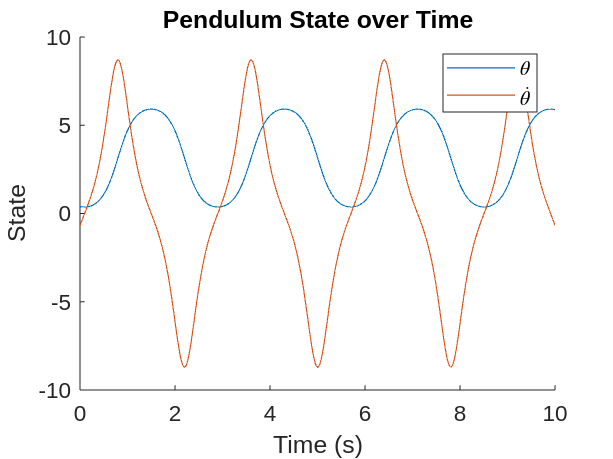

theta0 =0.4;
thetadot0 = -0.7;

m = 1; g = 9.81; L = 0.5;
params.m = m; params.g = g; params.L = L;
t0 = 0; tf = 10;

x0 = [theta0; thetadot0];
[t, x, ~] = continuousSim(@pendulum, @(x) 0, [t0, tf], x0, params);

figure;
hold on;
plot(t, x(:, 1))
plot(t, x(:, 2))
xlabel('Time (s)')
ylabel('State')
legend({'$\theta$', '$\dot{\theta}$'}, 'Interpreter', 'latex')
hold off
title('Pendulum State over Time')

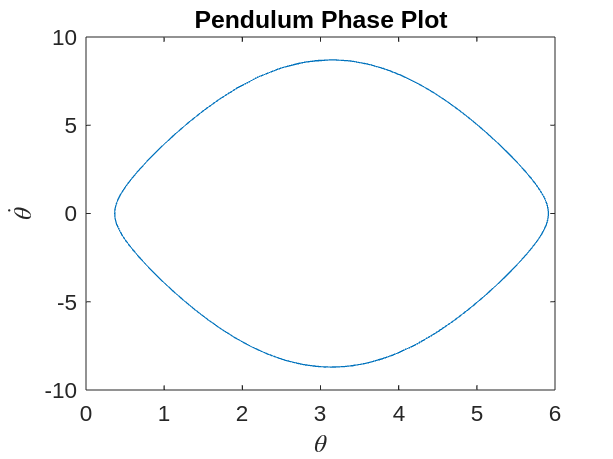


figure;
plot(x(:, 1), x(:, 2))
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
title('Pendulum Phase Plot')

## Linearizing the Pendulum about Equilibrium

To stabilize the pendulum upright, first consider linearizing the pendulum about the equilibrium $x^* = \left[ \matrix{0 & 0}\right]^T, u = 0$

Computing Jacobians, 


$$A(x) = \frac{\partial}{\partial x} \left(f(x) + g(x)u)  \\
= \left[ \matrix{0 & 1 \cr -\frac{g}{L}\cos\theta & 0}\right] \\
B(x) = \frac{\partial}{\partial u} \left(f(x) + g(x)u)  \\
= \left[ \matrix{0 \cr \frac{1}{mL^2}}\right]$$


Giving linearized dynamics about equilibrium


$$\dot{x} = \left[\matrix{0 & 1 \cr \frac{g}{L} & 0}\right]x + \left[\matrix{0 \cr \frac{1}{mL^2}} \right]u$$


Apend = [0 1; g/L 0];
Bpend = [0; 1 / (m * L^2)];

Now, compute a control law $u = -Kx$ using LQR

Qp = eye(2);
Rp = 1;

Kp = lqr(Apend, Bpend, Qp, Rp);

ctrl = @(x) - Kp * x;

And simulate the results

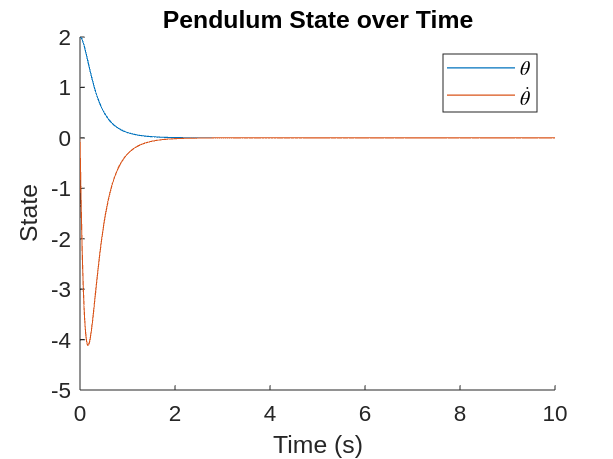

theta0ctrl =2;
thetadot0ctrl = 0;

x0 = [theta0ctrl; thetadot0ctrl];
[t, x, u] = continuousSim(@pendulum, ctrl, [t0, tf], x0, params);

figure;
hold on;
plot(t, x(:, 1))
plot(t, x(:, 2))
xlabel('Time (s)')
ylabel('State')
legend({'$\theta$', '$\dot{\theta}$'}, 'Interpreter', 'latex')
hold off
title('Pendulum State over Time')

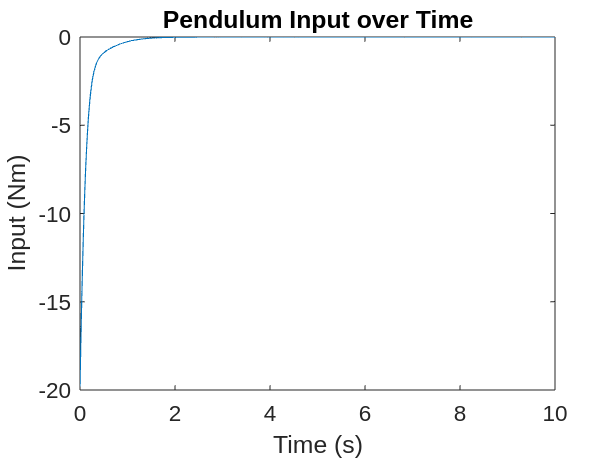


figure;
plot(t, u)
xlabel('Time (s)')
ylabel('Input (Nm)')
title('Pendulum Input over Time')

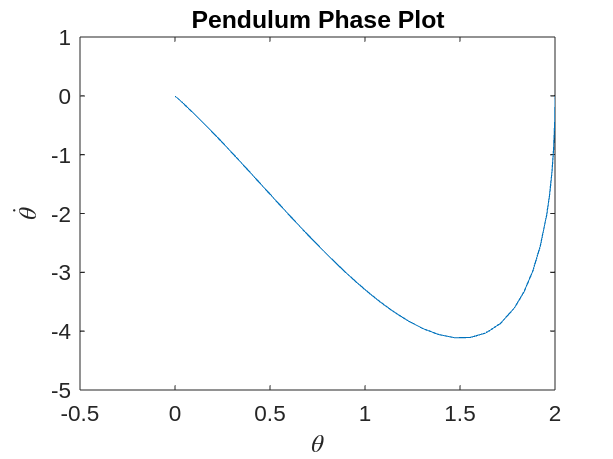


figure;
plot(x(:, 1), x(:, 2))
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
title('Pendulum Phase Plot')

Note that, impressively, the linearization is able to stablize the pendulum from any initial condition. However, note that the pendulum is *not smooth* around the bottom equilibrium position. As the initial condition passes from through the bottom equilibrium, the controller will discontinuously jump from applying positive torque to negative torque, and is therefore not smooth. 

## Dynamics of the Cartpole

Next, we consider a more complicated dynamical system, the cartpole, pictured in the figure below. 

Consider the state $x = \left[ \matrix{x & \theta & \dot{x} & \dot{\theta} }\right]^T$ and input $u = F$. In a slightly more complicated analysis, the dynamics of the cartpole can be computed via Lagrangian mechanics. The kinetic energy is


$$T = \frac{1}{2}(M + m)\dot{x}^2 + \frac{1}{2}mL^2\dot{\theta}^2-mL\cos\theta \dot{\theta}\dot{x}$$


and the potential energy is


$$V = mgL\cos\theta$$


The Lagrangian is given $L = T-V$. Computing the relevant derivatives


$$\frac{\partial L}{\partial x} = 0 \\
\frac{\partial L}{\partial \dot{x}} = (M + m)\dot{x} - mL\cos\theta \dot{\theta} \\
\frac{d}{dt} \left(\frac{\partial L}{\partial \dot{x}}\right) = mL^2\ddot{\theta} - mL\sin\theta\dot{\theta}^2 -mL\cos\theta\ddot{\theta} \\
\frac{\partial L}{\partial \theta} = mL\sin\theta\dot{\theta}\dot{x} + mgL\sin\theta \\
\frac{\partial L}{\partial \dot{\theta}} = mL^2\dot{\theta}-mL\cos\theta\dot{x}\\
\frac{d}{dt} \left(\frac{\partial L}{\partial \dot{\theta}}\right) = mL^2 \ddot{\theta}-mL\cos\theta\ddot{x} + mL\sin\theta\dot{\theta}\dot{x}$$


Then, the accelerations can be computed from $\frac{d}{dt}\left( \frac{\partial L}{\partial \dot{\theta}}\right) - \frac{\partial L}{\partial \theta} = 0$, since the pendulum joint is unactuated, and $\frac{d}{dt}\left( \frac{\partial L}{\partial \dot{x}}\right) - \frac{\partial L}{\partial x} = F$. Solving the system of two nonlinear equations gives:


$$\ddot{x} = \frac{-mL\sin\theta\dot{\theta}^2+mg\sin\theta\cos\theta+F}{M+m(1-\cos^2{\theta}) \\
\ddot{\theta} = \frac{-mL\sin\theta\cos\theta \dot{\theta}^2+(M+m)g\sin\theta+\cos\theta F}{(M+m(1-\cos^2{\theta}))L}$$


Giving the state space equations for the cartpole


$$\left[\matrix{\dot{x} \cr \dot{\theta} \cr \ddot{x} \cr \ddot{\theta}}\right] = \left[\matrix{\dot{x} \cr \dot{\theta} \cr  \frac{-mL\sin\theta\dot{\theta}^2+mg\sin\theta\cos\theta}{M+m(1-\cos^2{\theta}) \cr \frac{-mL\sin\theta\cos\theta \dot{\theta}^2+(M+m)g\sin\theta}{(M+m(1-\cos^2{\theta}))L}}\right] + \left[ \matrix{0 \cr 0 \cr  \frac{1}{M+m(1-\cos^2{\theta})\cr \frac{\cos\theta}{(M+m(1-\cos^2{\theta}))L}}\right]u$$


m_cp = 1; M_cp = 1; L_cp = 1; g_cp = 9.81;
params_cp.m = m_cp; params_cp.M = M_cp;
params_cp.g = g_cp;params_cp.L = L_cp;

## Linearizine the Cartpole about Equilibrium

To stabilize the cartpole about upright, we linearize the system about the equilibrium point $x=0, u=0$. An additional assumption is made that $\dot{\theta}^2 \approx0$. Computing Jacobians


$$A = \left[ \matrix{0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 1 \cr 0 & \frac{m}{M}g & 0 & 0 \cr 0 & \frac{M+m}{M}\frac{g}{L} & 0 & 0 }\right] \\
B = \left[ \matrix{0 \cr 0 \cr \frac{1}{M} \cr \frac{1}{ML}}\right] $$


Acart = [
    0 0 1 0; 
    0 0 0 1; 
    0 params_cp.m / params_cp.M * params_cp.g 0 0;
    0 (params_cp.M + params_cp.m) / params_cp.M * params_cp.g / params_cp.L 0 0
];
Bcart = [0; 0; 1 / params_cp.M; 1 / (params_cp.M * params_cp.L)];

And again, compute a control law $u = -Kx$ using LQR

Qcp = eye(4);
Rcp = 1;

Kcp = lqr(Acart, Bcart, Qcp, Rcp);
ctrl_cp = @(x) - Kcp * x;

And simulate the results

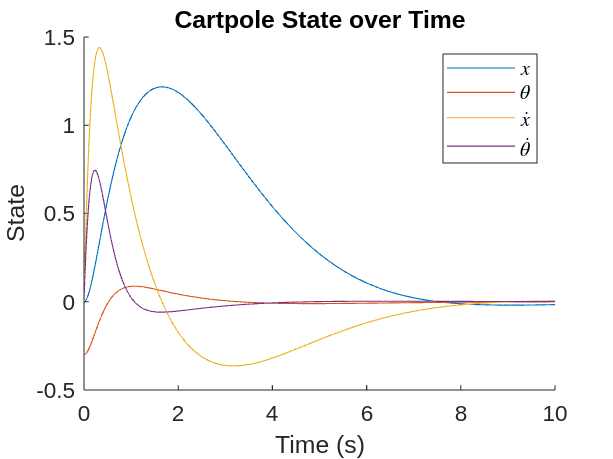

th0 =-0.3;
thdot0 = 0;
x0 = 0;
xdot0 = 0;
y0 = [x0; th0; xdot0; thdot0];
[tcp, xcp] = continuousSim(@cartpole, ctrl_cp, [t0, tf], y0, params_cp);

figure;
hold on;
plot(tcp, xcp(:, 1))
plot(tcp, xcp(:, 2))
plot(tcp, xcp(:, 3))
plot(tcp, xcp(:, 4))
xlabel('Time (s)')
ylabel('State')
legend({'$x$', '$\theta$', '$\dot{x}$', '$\dot{\theta}$'}, 'Interpreter', 'latex')
hold off
title('Cartpole State over Time')

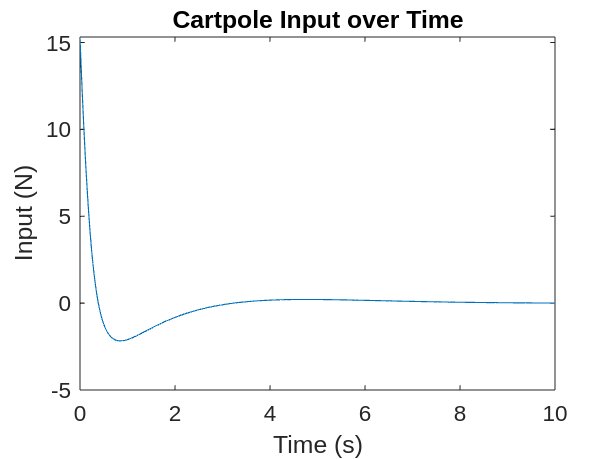


figure;
plot(tcp, -Kcp * xcp')
xlabel('Time (s)')
ylabel('Input (N)')
title('Cartpole Input over Time')

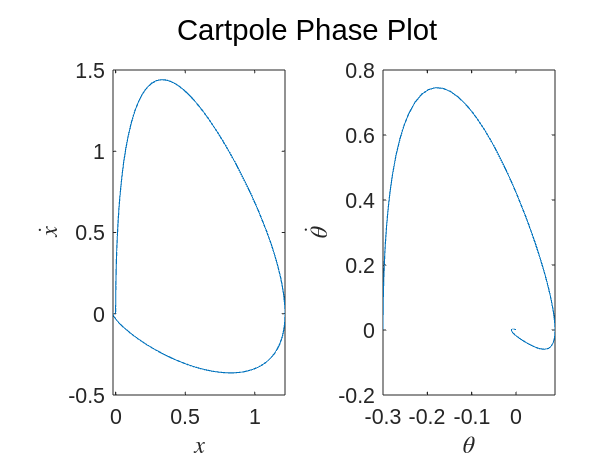


figure;
subplot(1, 2, 1)
plot(xcp(:, 1), xcp(:, 3))
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$\dot{x}$', 'Interpreter', 'latex')
subplot(1, 2, 2)
plot(xcp(:, 2), xcp(:, 4))
xlabel('$\theta$', 'Interpreter', 'latex')
ylabel('$\dot{\theta}$', 'Interpreter', 'latex')
sgtitle('Cartpole Phase Plot')

The results of linearization are, again, quite impressive close to the equilibrium point. However, notice that with the more complicated cartpole system, if the system is taken far from the original equilibrium, the controller fails to stabilize the system to the origin, and the system goes unstable.